## Úloha 1 - Dozimetrická měření

clc
clear
close all

Beta_us = [0.160 44.6 ];

## Úloha 2 - Impulzová charakteristika

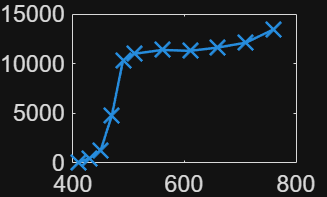

clc
clear
close all

Us_cal = 405; % Kalibracni napeti
n = 3; % Pocet stinitek

Us = [410 430 450 470 490 510 560 610 660 710 760];
n = [45 486 1296 4780 10354 10995 11379 11292 11622 12117 13458];

figure
    grid on
    title("Impulzová charakteristika GM trubice")
    xlabel("U [V]");
    ylabel("n [min^{-1}]")
    plot(Us, n, Marker='x',MarkerSize=13,LineWidth=1.5);
    fontsize(scale=1.4);

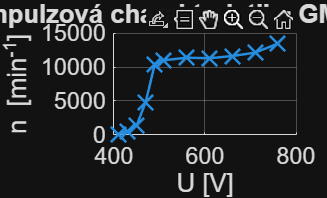


figure
    hold on
    grid on
    
    title("Impulzová charakteristika GM trubice")
    xlabel("U [V]")
    ylabel("n [min^{-1}]")
    plot(Us, n, Marker='x',MarkerSize=13,LineWidth=1.5)
    fontsize(scale=1.4);
    hold off;

## Úloha 3 - Mrtvá doba

clc
clear
close all

U = 600;
n = [ 21397 21635 24503;... % Prvni beta zaric
      42056 42328 42309;... % Oba dohromady
      24503 24439 24434];   % Druhy beta zaric


## Úloha 4 - Vliv přepážky

clc
clear
close all

U = 602; % Napeti 602 V
N = 0:1:10; % Pocet folii

d = 0.2 / 1000; % Tloustka folie mm -> m
d_vektor = d.*N;


## Úloha 5 - Hmotnostní koeficient útlumu

clc
clear
close all

% Struktura pro ukladani infa o materialech
%   d - delka[mm]
%   s - sirka[mm]
%   v - tloustka[mm]
%   m - hmotnost [g]
%   n - pocet pulzu [min^(-1)]

vz1 = struct('d', 128.55, 's', 98.1, 'v', 0.2, 'm', 3.13, 'n', 19579);
vz2 = struct('d', 149.9, 's', 100, 'v', 2.5, 'm', 49.52, 'n', 1840);
vz3 = struct('d', 119.4, 's', 99.9, 'v', 1, 'm', 20, 'n', 7139);
vz4 = struct('d', 150.4, 's', 100.25, 'v', 1.15, 'm', 39.98, 'n', 3442);
vz5 = struct('d', 101.2, 's', 100.4, 'v', 3.5, 'm', 34.36, 'n', 1801);
vz6 = struct('d', 98.6, 's', 101.1, 'v', 11.3, 'm', 69.11, 'n', 90);
vz7 = struct('d', 117, 's', 116.9, 'v', 38.73, 'm', 15.12, 'n', 13303);

% Vytvoreni pole struktur
vz = [vz1 vz2 vz3 vz4 vz5 vz6 vz7]

vz = 1×7 struct array with fields:
    d
    s
    v
    m
    n



V = @(l,s,d)(l*s*d)

V = function_handle with value:
    @(l,s,d)(l*s*d)


Ro = @(V,m)(m/V)

Ro = function_handle with value:
    @(V,m)(m/V)


sigma = @(Ro,w)(Ro*w)

sigma = function_handle with value:
    @(Ro,w)(Ro*w)



for i = 1:7
    V_vector(i) = V(vz(i).d/1000, vz(i).s/1000, vz(i).v/1000)
    Ro_vector(i) = Ro(V_vector(i), vz(i).m/1000)
    sigma_vector(i) = sigma(Ro_vector(i), vz(i).v/1000)
    n_vector(i) = vz(i).n/60
end    

V_vector = 2.5222e-06

Ro_vector = 1.2410e+03

sigma_vector = 0.2482

n_vector = 326.3167

V_vector = 1.0e-04 *

    0.0252    0.3748


Ro_vector = 1.0e+03 *

    1.2410    1.3214


sigma_vector =     0.2482    3.3035


n_vector =   326.3167   30.6667


V_vector = 1.0e-04 *

    0.0252    0.3748    0.1193


Ro_vector = 1.0e+03 *

    1.2410    1.3214    1.6767


sigma_vector =     0.2482    3.3035    1.6767


n_vector =   326.3167   30.6667  118.9833


V_vector = 1.0e-04 *

    0.0252    0.3748    0.1193    0.1734


Ro_vector = 1.0e+03 *

    1.2410    1.3214    1.6767    2.3058


sigma_vector =     0.2482    3.3035    1.6767    2.6516


n_vector =   326.3167   30.6667  118.9833   57.3667


V_vector = 1.0e-04 *

    0.0252    0.3748    0.1193    0.1734    0.3556


Ro_vector = 1.0e+03 *

    1.2410    1.3214    1.6767    2.3058    0.9662


sigma_vector =     0.2482    3.3035    1.6767    2.6516    3.3817


n_vector =   326.3167   30.6667  118.9833   57.3667   30.0167


V_vector = 1.0e-03 *

    0.0025    0.0375    0.0119    0.0173    0.0356    0.1126


Ro_vector = 1.0e+03 *

    1.2410    1.3214    1.6767    2.3058    0.9662    0.6135


sigma_vector =     0.2482    3.3035    1.6767    2.6516    3.3817    6.9329


n_vector =   326.3167   30.6667  118.9833   57.3667   30.0167    1.5000


V_vector = 1.0e-03 *

    0.0025    0.0375    0.0119    0.0173    0.0356    0.1126    0.5297


Ro_vector = 1.0e+03 *

    1.2410    1.3214    1.6767    2.3058    0.9662    0.6135    0.0285


sigma_vector =     0.2482    3.3035    1.6767    2.6516    3.3817    6.9329    1.1055


n_vector =   326.3167   30.6667  118.9833   57.3667   30.0167    1.5000  221.7167



exp_reg = fit(sigma_vector', n_vector','exp1')

exp_reg =      General model Exp1:
     exp_reg(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       400.3  (338.4, 462.3)
       b =     -0.6836  (-0.843, -0.5242)

exp_plot = coeffvalues(exp_reg)

exp_plot =   400.3490   -0.6836


sigma_reg = 0:0.05:8

sigma_reg =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


reg_plot = exp_plot(1) .* exp(sigma_reg.*exp_plot(2))

reg_plot =   400.3490  386.8960  373.8951  361.3310  349.1892  337.4553  326.1158  315.1572  304.5670  294.3326  284.4421  274.8839  265.6469  256.7204  248.0938  239.7570  231.7004  223.9146  216.3903  209.1189  202.0919  195.3010  188.7382  182.3960  176.2669  170.3438  164.6197  159.0880  153.7421  148.5759  143.5833  138.7584  134.0957  129.5897  125.2351  121.0268  116.9599  113.0297  109.2315  105.5610  102.0138   98.5858   95.2730   92.0716   88.9777   85.9877   83.0983   80.3059   77.6074   74.9995


mu = -exp_plot(2) .* Ro_vector

mu = 1.0e+03 *

    0.8484    0.9033    1.1462    1.5762    0.6605    0.4194    0.0195


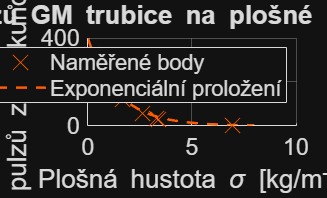


figure
    hold on
    grid on
    
    title("Závislost počtu impulzů GM trubice na plošné hustotě vzorku pro \beta zářič")
    xlabel("Plošná hustota \sigma [kg/m^{-2}]")
    ylabel("Počet pulzů za sekundu n [s^{-1}]")
    plot(sigma_vector,n_vector, 'LineStyle','none', Marker='x', MarkerSize=13,Color="#FF5C00");
    plot(sigma_reg, reg_plot, "LineStyle","--", "Color",'#FF5C00', 'LineWidth',1.5 );
    legend('Naměřené body', 'Exponenciální proložení')
    fontsize(scale=1.4);
    hold off;

## Úloha 6 - Nejistota určení hustoty

rozmery = [vz4.d vz4.s vz4.v] / 1000; % [mm -> m]
m_vector =  [39.18 39.19 39.16 39.16 39.17 39.17 39.15 39.16 39.20 39.17] / 1000; % hmotnost [g -> kg]

err_suplera = 0.05 / 1000

err_suplera = 5.0000e-05

suplera_weight = sqrt(2)

suplera_weight = 1.4142


uc_rozmer = err_suplera / suplera_weight

uc_rozmer = 3.5355e-05


uc_vaha1 = uc_rozmer * rozmery(1) * rozmery(2)

uc_vaha1 = 5.3307e-07

uc_vaha2 = uc_rozmer * rozmery(3) * rozmery(2)

uc_vaha2 = 4.0760e-09

uc_vaha3 = uc_rozmer * rozmery(1) * rozmery(3)

uc_vaha3 = 6.1151e-09


rozmery(1) * rozmery(2)

ans = 0.0151

rozmery(3) * rozmery(2)

ans = 1.1529e-04

rozmery(1) * rozmery(3)

ans = 1.7296e-04


uc_objem = geometricSum([uc_vaha1, uc_vaha2, uc_vaha3])

uc_objem = 5.3312e-07


ua_m = typeAUncertainty(m_vector)

ua_m = 4.8189e-06

err_vaha = 0.01/1000

err_vaha = 1.0000e-05

ub_m = err_vaha / sqrt(3)

ub_m = 5.7735e-06


uc_hmotnost = geometricSum([ua_m ub_m])

uc_hmotnost = 7.5203e-06


hmotnost = mean(m_vector)

hmotnost = 0.0392

objem = rozmery(1)*rozmery(2)*rozmery(3)

objem = 1.7339e-05


uc_vaha_m = (1/objem) * uc_hmotnost

uc_vaha_m = 0.4337

uc_vaha_v = (-hmotnost/(objem^2)) * uc_objem

uc_vaha_v = -69.4597

(1/objem)

ans = 5.7673e+04

(-hmotnost/(objem^2))

ans = -1.3029e+08

hustota = hmotnost/objem

hustota = 2.2591e+03


uc_hustota = geometricSum([uc_vaha_v  uc_vaha_m])

uc_hustota = 69.4611


U_hustota = 2 * uc_hustota

U_hustota = 138.9221

## Úloha 7 - Gamma zářič

n_gamma = [177 167 202 171 170 155 189] ./ 60; %[min^(-1) -> s^(-1)]

%[I_gamma, mu_gamma] = metoda_nejm_ctvercu(sigma_vector, n_gamma)
%linear_gamma = I_gamma.*sigma_reg + mu_gamma

exp_reg_gamma = fit(sigma_vector', n_gamma','exp1')

exp_reg_gamma =      General model Exp1:
     exp_reg_gamma(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =        3.18  (2.844, 3.516)
       b =    -0.03027  (-0.06368, 0.003147)

exp_plot_gamma = coeffvalues(exp_reg_gamma)

exp_plot_gamma =     3.1803   -0.0303


sigma_reg = 0:0.05:8

sigma_reg =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


reg_plot_gamma = exp_plot_gamma(1) .* exp(sigma_reg.*exp_plot_gamma(2))

reg_plot_gamma =     3.1803    3.1755    3.1707    3.1659    3.1611    3.1563    3.1516    3.1468    3.1420    3.1373    3.1325    3.1278    3.1231    3.1184    3.1136    3.1089    3.1042    3.0995    3.0948    3.0902    3.0855    3.0808    3.0762    3.0715    3.0669    3.0622    3.0576    3.0530    3.0484    3.0437    3.0391    3.0346    3.0300    3.0254    3.0208    3.0162    3.0117    3.0071    3.0026    2.9980    2.9935    2.9890    2.9844    2.9799    2.9754    2.9709    2.9664    2.9620    2.9575    2.9530


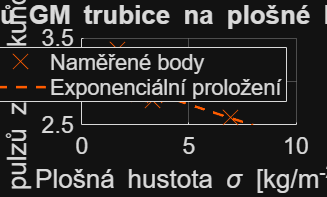

%mu = -exp_plot(2) .* Ro_vector



figure
    hold on
    grid on
    title("Závislost počtu impulzů GM trubice na plošné hustotě vzorku pro \gamma zářič")
    xlabel("Plošná hustota \sigma [kg/m^{-2}]")
    ylabel("Počet pulzů za sekundu n [s^{-1}]")
    plot(sigma_vector,n_gamma, 'LineStyle','none', Marker='x', MarkerSize=13, Color="#FF5C00");
    plot(sigma_reg, reg_plot_gamma, "LineStyle","--", "Color",'#FF5C00', 'LineWidth',1.5 );
    legend('Naměřené body', 'Exponenciální proložení')
    fontsize(scale=1.4);
    hold off;